% Get the input arrays directly from the user
x = input('Enter the first array: ');
nx=input('index of [x]');
h = input('Enter the second array: ');
nh=input('index of [h]')

nh = 0

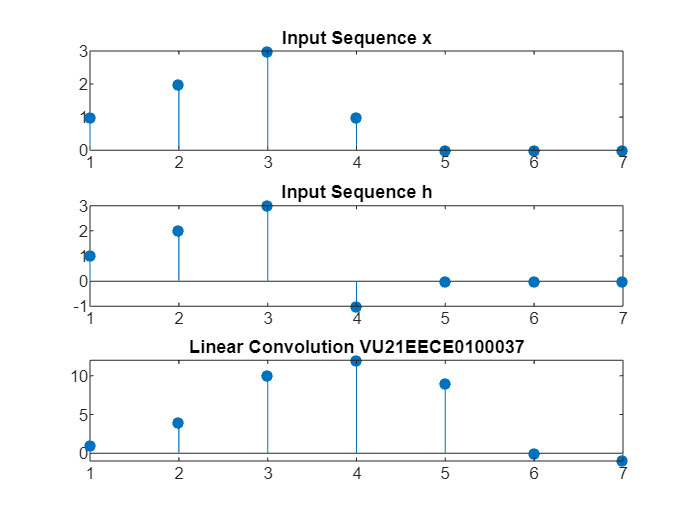

% Step 1: Determine the lengths of the input arrays
m = length(x);
n = length(h);

% Step 2: Determine the length of the output array
len_Y = m + n - 1;

% Step 3: Pad the input arrays with zeros to match the length of the output array
x = [x, zeros(1, len_Y - m)];
h = [h, zeros(1, len_Y - n)];

% Step 4: Initialize the output array for linear convolution
Y = zeros(1, len_Y);

% Step 5: Perform linear convolution using loops
for i = 1:len_Y
    for j = 1:m
        if i - j + 1 > 0 && i - j + 1 <= n
            Y(i) = Y(i) + x(j) * h(i - j + 1);
        end
    end
end

% Display the result graphically using stem plot
figure;
subplot(3, 1, 1);
stem(x, 'filled', 'MarkerSize', 5);
title('Input Sequence x');

subplot(3, 1, 2);
stem(h, 'filled', 'MarkerSize', 5);
title('Input Sequence h');

subplot(3, 1, 3);
stem(Y, 'filled', 'MarkerSize', 5);
title('Linear Convolution VU21EECE0100037');